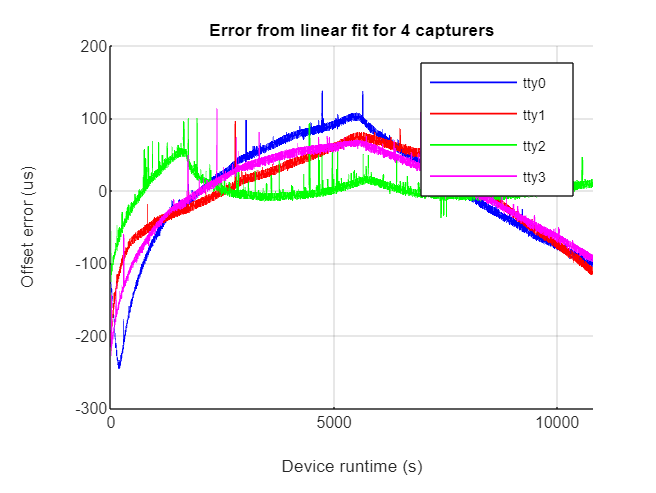

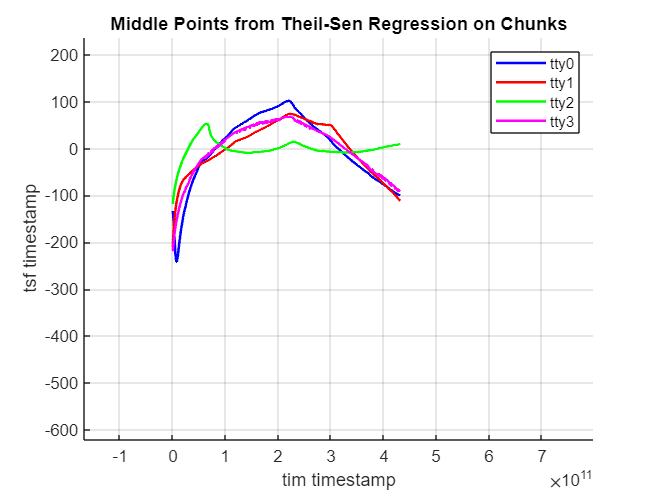

warning('off','all')


tim_freq_hz = 40000000;
tsf_freq_hz = 1000000;
samplerate_hz = 100;
downsample_period = 2;
downsample_rate = samplerate_hz / downsample_period; % 100 SPS downsampled by 5 -> 20 SPS
chunk_length_s = 5; % Chunk length in seconds
files = {'tty0.txt', 'tty1.txt', 'tty2.txt', 'tty3.txt'};
colors = {'b-', 'r-', 'g-', 'm-'};

tsf_offsets = [];
all_chunks = cell(length(files), 1); % Store chunks for all files

% Calculate the number of samples per chunk using downsampled rate
samples_per_chunk = chunk_length_s * downsample_rate;

% Find the common offset
for i = 1:length(files)
    first_line = dlmread(['./data/', files{i}], '', [0 0 0 1]);
    tsf_offsets(end+1) = first_line(2);
end

common_tsf_offset = min(tsf_offsets);

figure;
hold on;

for i = 1:length(files)
    data = dlmread(['./data/', files{i}]);
    tim_timestamps_arr = data(:,1) - data(1,1);
    tsf_timestamps_arr = data(:,2) - common_tsf_offset;

    % Downsample by taking every 5th sample (20% of the data)
    idx = 1:5:length(tim_timestamps_arr);
    tim_timestamps_arr = tim_timestamps_arr(idx);
    tsf_timestamps_arr = tsf_timestamps_arr(idx);

    % Compute linear fit
    p = polyfit(tim_timestamps_arr, tsf_timestamps_arr, 1);
    tsf_predicted = polyval(p, tim_timestamps_arr);
    error_tsf = tsf_predicted - tsf_timestamps_arr;

    % Split into fixed-size chunks
    chunks = {};
    num_chunks = floor(length(tim_timestamps_arr) / samples_per_chunk);
    for j = 1:num_chunks
        start_idx = (j-1) * samples_per_chunk + 1;
        end_idx = j * samples_per_chunk;
        chunks{end+1} = [tim_timestamps_arr(start_idx:end_idx), error_tsf(start_idx:end_idx)];
    end
    all_chunks{i} = chunks;

    % Plot the downsampled data
    plot(tim_timestamps_arr / tim_freq_hz, error_tsf, colors{i}, 'LineWidth', 1);
end

xlabel('Device runtime (s)');
ylabel('Offset error (us)');
title('Error from linear fit for 4 capturers');
legend('tty0', 'tty1', 'tty2', 'tty3');
grid on;
hold off;

%% Theil-Sen Regression on Chunks and Finding Middle Points (Line Plot)
% Assumption: 'all_chunks' is a cell array where each cell corresponds to a file,
% and each file cell contains a cell array of chunks.
% Each chunk is a matrix with two columns: 
%   column 1: tim timestamp 
%   column 2: tsf timestamp
%
% The function [slope, intercept, std_err] = theilSenRegression(x, y) is assumed to be implemented.

num_files = length(all_chunks);
regression_params = cell(num_files, 1); % To store [slope, intercept, std_err] per chunk
middle_points = cell(num_files, 1);     % To store the middle point for each chunk: [x_mid, y_mid]

figure;
hold on;
colors = {'b-', 'r-', 'g-', 'm-'};

for i = 1:num_files
    file_chunks = all_chunks{i};  % cell array of chunks for file i
    num_chunks = length(file_chunks);
    regression_params{i} = zeros(num_chunks, 3); % Each row: [slope, intercept, std_err]
    middle_points{i} = zeros(num_chunks, 2);     % Each row: [x_mid, y_mid]
    
    for j = 1:num_chunks
        chunk_data = file_chunks{j};
        % Extract tim and tsf timestamps from the chunk
        x = chunk_data(:,1);
        y = chunk_data(:,2);
        
        % Compute the regression parameters using the Theil-Sen estimator
        [slope, intercept, std_err] = theilSenRegression(x, y);
        regression_params{i}(j,:) = [slope, intercept, std_err];
        
        % Define the middle point as the regression line value at the midpoint of x
        x_mid = (min(x) + max(x)) / 2;
        y_mid = slope * x_mid + intercept;
        middle_points{i}(j,:) = [x_mid, y_mid];
    end
    
    % Plot the middle points as a line
    plot(middle_points{i}(:,1), middle_points{i}(:,2), colors{i}, 'LineWidth', 1.5);
end


xlabel('tim timestamp');
ylabel('tsf timestamp');
title('Middle Points from Theil-Sen Regression on Chunks');
legend('tty0', 'tty1', 'tty2', 'tty3');
grid on;
hold off;



function [slope, intercept, std_err] = theilSenRegression(x, y)
    % Implements the Theil-Sen estimator for linear regression.
    n = length(x);
    slopes = zeros(n*(n-1)/2,1);
    count = 0;
    % Compute slopes between all pairs (i < j)
    for i = 1:n-1
        for j = i+1:n
            if abs(x(j) - x(i)) > eps
                count = count + 1;
                slopes(count) = (y(j) - y(i)) / (x(j) - x(i));
            end
        end
    end
    % Use the median slope as the estimate
    slope = median(slopes(1:count));
    % Compute intercept as median of (y - slope*x)
    intercept = median(y - slope * x);
    residuals = y - (slope * x + intercept);
    std_err = std(residuals);
end
